# Draw ACC2

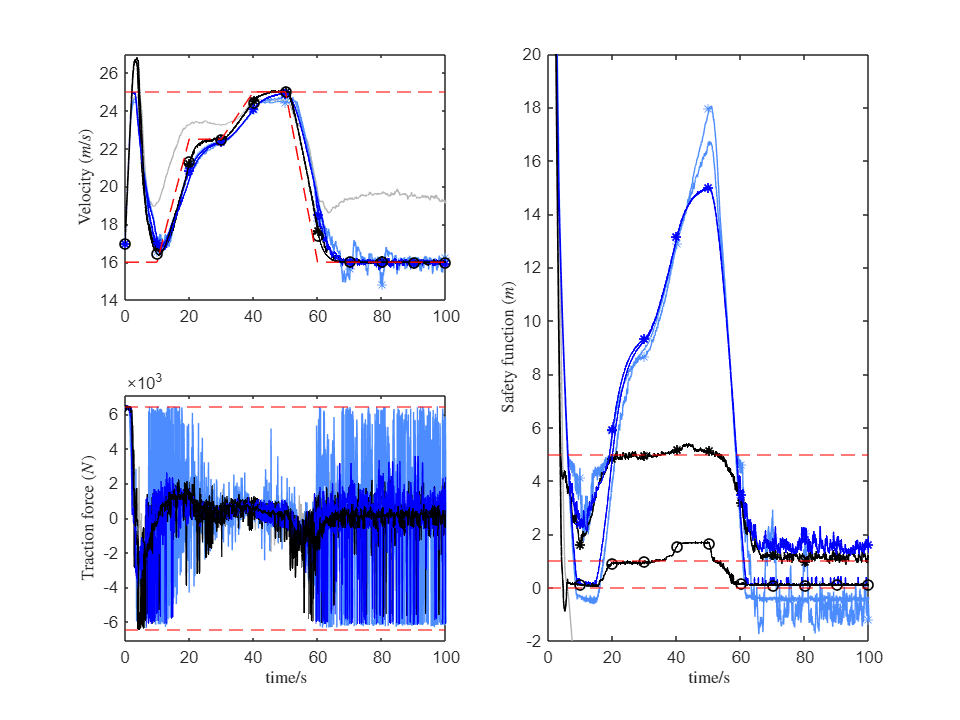

% Define parameters
two_column_width = 8; 
font_size = 10;

% Colors: Recursive feasibility (none=black (gray, uncertainty not considered), yes=blue (light blue, uncertainty not considered))
colors = {[0.7 0.7 0.7], '#4C8CFF', '#4C8CFF', 'k', 'b', 'b', 'k'};

lineStyles = {'-', '-', '-', '-', '-', '-', '-'};  
linewidth = {0.5, 0.5, 0.5, 1, 1, 1, 1};  % Different line widths to differentiate

% Markers: Margin (none='', 10='*', 1='s')
markers = {'none', 'none', '*', '*', 'none', '*', 'o'};  

time_step = 10;

legend_labels = {'without all', 'with recursive feasibility', 'with recursive feasibility and margin=10', ...
                 'with robustness', 'with robustness and recursive feasibility', 'with all(margin=10)', 'with all(margin=1)'};

figure;
set(gcf, 'Units', 'inches', 'Position', [1, 1, two_column_width, two_column_width*0.75]);

for i = 1:7
    % Velocity
    subplot(2,2,1);
    time_data = outANS(i).X.time;
    value_data = outANS(i).X.signals.values(:,2);
    plot(time_data, value_data, ...
        'Color', colors{i}, 'LineStyle', lineStyles{i}, ...
        'LineWidth', linewidth{i}, 'Marker', markers{i}, ...
        'MarkerIndices', 1:floor(length(time_data)/time_step):length(time_data)); hold on;

    % Traction force
    subplot(2,2,3);
    time_data = outANS(i).U.time;
    value_data = squeeze(outANS(i).U.signals.values);
    plot(time_data, value_data, ...
        'Color', colors{i}, 'LineStyle', lineStyles{i}, ...
        'LineWidth', linewidth{i}); hold on;

    % Safety function
    subplot(2,2,[2,4]);
    time_data = outANS(i).X.time;
    value_data = outANS(i).X.signals.values * Ac';
    plot(time_data, value_data, ...
        'Color', colors{i}, 'LineStyle', lineStyles{i}, ...
        'LineWidth', linewidth{i}, 'Marker', markers{i}, ...
        'MarkerIndices', 1:floor(length(time_data)/time_step):length(time_data)); hold on;
end

% First subplot: Velocity
subplot(2,2,1);
% title('Vehicle velocity');
axis([0 100 14 27]);
plot([0, 10, 20, 30, 40, 50, 60, 100],[16, 16, 22.5, 22.5, 25, 25,16, 16],'--','color','red');  
yline(25, '--r','LineWidth',0.2);  
ylabel('Velocity ($m/s$)', 'Interpreter', 'latex', 'FontSize', font_size);
% xlabel('$\mathrm{time/s}$', 'Interpreter', 'latex', 'FontSize', font_size);
set(gca, 'FontSize',font_size);
set(findall(gca, 'Type', 'text'), 'FontSize',font_size);
set(findall(gcf, '-property', 'FontSize'), 'FontSize', font_size);
set(gca,'LooseInset',get(gca,'TightInset'))

% Second subplot: Traction force
subplot(2,2,3);
% title('Traction force');
axis([0 100 -1.1*um*M*g 1.1*um*M*g]);
yline(um*M*g, '--r','LineWidth',0.2);  
yline(-um*M*g, '--r','LineWidth',0.2);  
ylabel('Traction force ($N$)', 'Interpreter', 'latex', 'FontSize', font_size);
xlabel('$\mathrm{time/s}$', 'Interpreter', 'latex', 'FontSize', font_size);
set(gca, 'FontSize',font_size);
set(findall(gca, 'Type', 'text'), 'FontSize',font_size);
set(findall(gcf, '-property', 'FontSize'), 'FontSize', font_size);
ax = gca;
ax.YAxis.Exponent = 3; 
set(gca,'LooseInset',get(gca,'TightInset'))

% Third subplot: Safety function
subplot(2,2,[2,4]);
axis([0 100 -2 20]);
set(gca, 'FontSize',font_size);
yline(5, '--r','LineWidth',0.2);  
yline(1, '--r','LineWidth',0.2);  
yline(0, '--r','LineWidth',0.2);
% title('Safety function');
ylabel('Safety function ($m$)', 'Interpreter', 'latex', 'FontSize', font_size);
xlabel('$\mathrm{time/s}$', 'Interpreter', 'latex', 'FontSize', font_size);
set(findall(gca, 'Type', 'text'), 'FontSize',font_size);
set(findall(gcf, '-property', 'FontSize'), 'FontSize', font_size);
set(gca,'LooseInset',get(gca,'TightInset'))

% Export the figure
exportgraphics(gcf, 'Figures\ACC2.eps','ContentType','vector');